# Ejercicio de Aplicación. 

## Dispersión o Scattering

Se considerra como el esparcimiento o cambio de dirección de la luz en múltiples ángulos durante su propagación a través de un medio transparente, que se manifiesta en la salida como un ensanchamiento del pulso de entrada.

Se  calcula el ensanchamiento producido  en un pulso gaussiano de T0 picosegundos (ps) de ancho cuando se propaga en tercera ventana por una fibra optica de ‘z’ Km de largo, teniendo en cuenta los efectos de la segunda y la tercera derivada (sin tener en cuenta la atenuacion y el retardo de grupo (primera derivada)

El parámetro D es el parámetro de dispersión y se expresa en ps/(Km-nm). y esta dado por la expresión 


$$D=\frac{\mathrm{S0}}{4}\left(\frac{\lambda -\lambda_0^3 }{\lambda^4 }\right)$$
  

s0 es la pendiende de dispersion para fibras monomodo s0 = 0.090

por otro lado si se considera que la respuesta impulsiva de la fibra es:

$h\left(z,t\right)\longrightarrow H\left(z,\omega \right)$= $e^{-\frac{\alpha }{2}\;z} \;e^{-j\left(\beta \left(\omega \right)z\right)}$

el primer término es responsable de la atenuación, y se para este ejercicio puede considerar constante, pero debido las componentes espectrales de $\beta \left(\omega \right)\;\mathrm{difieren}\;\mathrm{de}\;\beta_0 \;$, se debe considerar de manera independiente cada componente.

La idea es, entonces,  calcular la transformada de Fourier del pulso a la entrada, propagar cada componente espectral independientemente y luego calcular la transformada inversa. De esta forma al desarrollar en series de taylor para  $\beta \left(\omega \right)$ y obtiene:

- $e^{\left(-\mathrm{jz}\frac{\beta_0^{\prime } }{1}\bigtriangleup \omega \right)}$     Introduce un retardo lineal de fase, que el el dominio del tiempo es:       $t=z-\beta_0$  

- $e^{\left(-\mathrm{jz}\frac{\beta_0^{\prime \prime } }{2}\bigtriangleup \omega^2 \right)}$ Variación cuadrática de fase. dispersión por diferentes velocidades de las componenntes espectrales. Produce ensanchamiento del pulso.

- $e^{\left(-\mathrm{jz}\frac{\beta_0^{\prime^{\prime } \prime } }{3!}\bigtriangleup \omega^3 \right)}$ Término mas significativo para pulsos del ancho del orden de picosegundos.

Según esto el procedimiento a seguir es el siguiente:

- Generar el pulso gausiano

- calcular la transformada rádida de fourier del pulso

- Calcular la respuesta al impulso de la FO considearndo $\alpha =0$

- Multiplicar las dos expresiones obtenidas para obtener la respuesta frecuencial

- Realizar la anti transformada para obtener la respuesta en el tiempo.

-  Graficar los resultados

La expresión de un pulso gaussiano de anchura eficaz T0, normalizado de manera que su energía (área bajo la curva de potencia instantánea) sea igual a la unidad, es la siguiente: 

  
$$p\left(t\right)=\frac{1}{\sqrt{2\pi \mathrm{T0}}}{*\;e}^{-\left(\frac{t^2 }{2{\mathrm{T0}}^2 }\right)}$$


clear 
z =300% Longitud de la fibra en Km

z = 300

T0 =20% Ancho del pulso en ps

T0 = 20

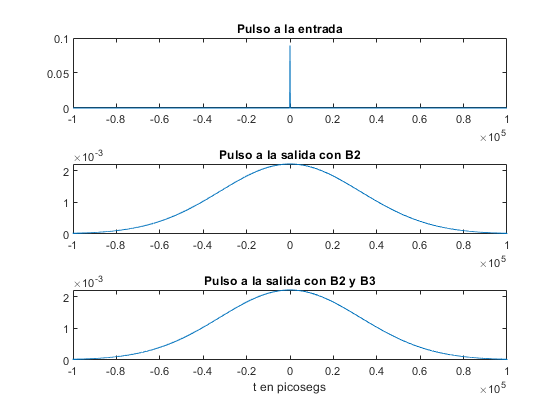

So = 0.090;
lambda = 1550;
lambdao = 1312;
c = 3e5;
t=(-1000: 1/10:1000);  % vector de tiempos para el pulso gaussiano en ps
Ao=1/(sqrt(2*pi*T0));
% Vector de tiempos de la gaussiana
t=[-100000: 1/10:100000];
% Gaussiana, E(z=0,t):
Et=Ao*exp(-t.^2/(2*(T0^2)));
subplot(3,1,1)
plot(t,Et);
title('Pulso a la entrada')
% Calculamos la transformada de fourier de la gaussiana
gaussfourier=fft(Et);
gaussfourier=fftshift(gaussfourier);
% Caracterizamos la fibra como un sistema lineal
% Calculamos alfa (No trabajaremos en este apartado con atenuacion)
alfa=0;
% Calculamos B1 (ps/Km)
B1=0;
% Calculamos B2 (ps^2/Km)
Dispersion=(So/4)*(lambda-(lambdao^4)/(lambda^3));
B2=(Dispersion*(lambda^2))/(2*pi*c);
% Calculamos B3
% Primero calculamos la derivada de la dispersion en lamda de trabajo
DerivDisp=(So/4)+((So*lambdao^4)/4)*3*lambda^-4;
% Sustituimos en la formula
B3=DerivDisp*((lambda^2)/(2*pi*c))^2;
% Definimos un vector de frecuencias
Af=(0:(length(gaussfourier)-1))*100/(1*length(gaussfourier))-50;
% La expresion en frecuencia de nuestro filtro lineal que caracteriza
% la fibra teninendo en cuenta B1,B2 y B3 es H:
H1=exp(Af.*2*pi*-i*z*B1);
H2=exp((Af.^2)*(2^2)*(pi^2)*-i*z*B2/2);
H3=exp((Af.^3)*(2^3)*(pi^3)*-i*z*B3/6);
Haux=H1.*H2; % Haux: Respuesta impulsiva en W de la fibra con B2
H=Haux.*H3; % H: Respuesta impulsiva en W de la fibra con B2 y B3
% Calculamos la respuesta en frecuencia de la entrada multimplicando
% la transformada de fourier del pulso gaussiano x la respuesta en
% frecuencia del filtro:
resw1=gaussfourier.*Haux;
resw=gaussfourier.*H;
resw1=fftshift(resw1); % Respuesta a la gaussiana en W de la fibra
%con B2
resw=fftshift(resw); % Respuesta a la gaussiana en W de la fibra
% con B2 y B3
% Pasamos al dominio del tiempo
rest1=ifft(resw1); % Respuesta a la gaussiana en t de la fibra
% con B2
rest=ifft(resw); % Respuesta a la gaussiana en t de la fibra
% con B2 y B3
% Dibujamos la respuesta a la gaussiana en t de la fibra con B2
subplot(3,1,2);
plot(t,abs(rest1));
title('Pulso a la salida con B2')
% Dibujamos la respuesta a la gaussiana en t de la fibra con B2 y B3
subplot(3,1,3);
plot(t,abs(rest));
title('Pulso a la salida con B2 y B3')
xlabel('t en picosegs')